# Principal Component Analysis

- Understand Principal Component Analysis (PCA), Derivation, Limitations

- Understand Linear Discriminant Analysis (LDA), Derivation, Limitations

## Principal Component Analysis

The [Principal Component Analysis](https://en.wikipedia.org/wiki/Principal_component_analysis) (PCA) is used when you have data that is collected on a large number of variables from a single population and contains correlated noise. For example, data that rates places using variables such as climate and terrain, housing, health care, education, crime, transportation, etc. The higher the number of variables, the more difficult it will be to interpret the dispersion matrix properly. There would be too many pairwise correlations between the variables to consider, and even graphical display of the data is not particular helpful (with 12 variables you will get more than 200 three-dimensional scatterplots to study). To get a more meaningful representation of your data, it is necessary to reduce the number of variables to a few interpretable *linear combinations *of the data. Therefore, PCA is an *unsupervised* way of measuring the *variance* in your dataset. Each linear combination of the data will correspond to a *principal component*.  

Lets assume that we have a dataset with only two dimensions, like (height, weight) or (x1, x2). This dataset can be plotted as points in a plane. But if we want to tease out variation, PCA finds a vector with most of the variance. The direction of your variance is the line *u *and plotting your data using only *u *gives a new coordinate system in which every point has a new (x,y) value. These axes don't actually mean anything physical; they're combinations of height and weight, the *principal components,* that are chosen to give one axes lots of variation. Check this [visual explanation of PCA ](http://setosa.io/ev/principal-component-analysis/)to see how this works. 

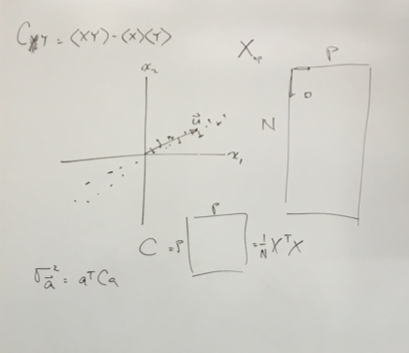

The variance associated with your vector $(\sqrt{\vec{a}})^2 = a^TCa$  

So, now you know what a PCA is, look at the PCA below. Is this a good PCA?

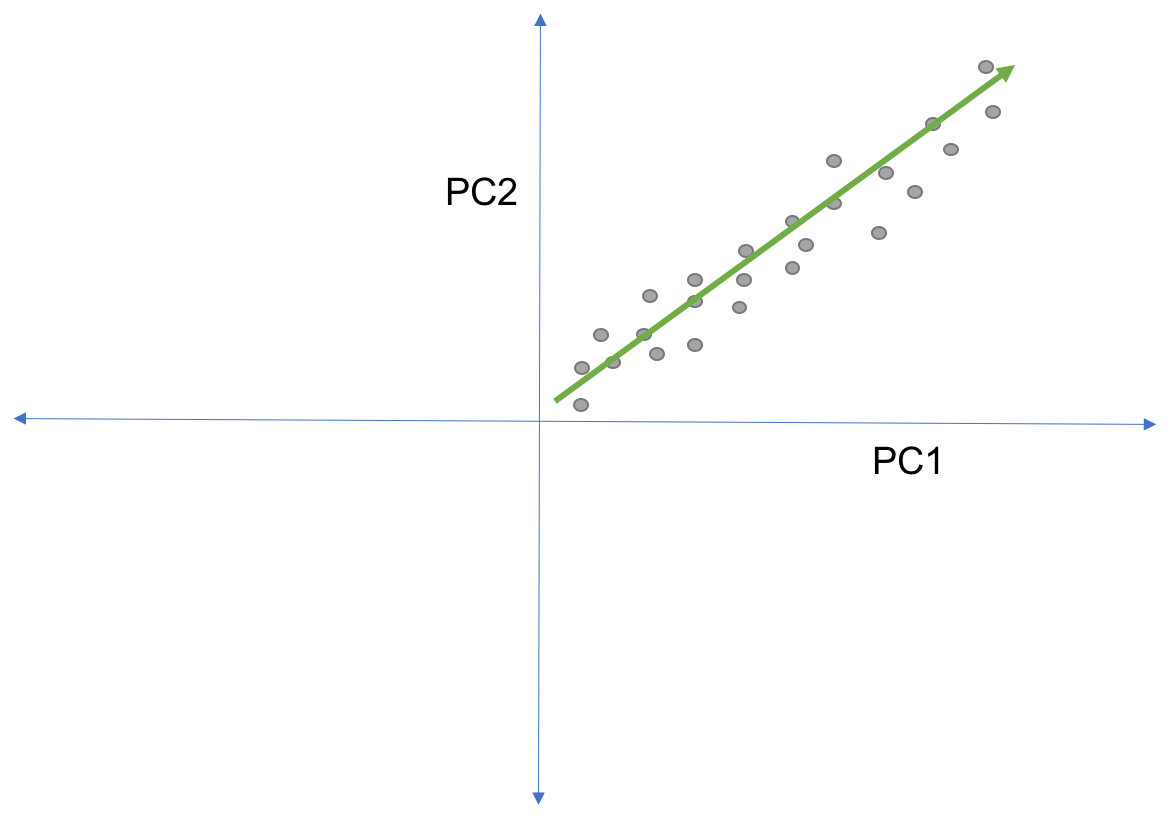

No, as PC1 should not correlate with PC2. Therefore, this is not a well performed PCA. 

## Co-variance matrix

To get the vector *u*, you need to find the [co-variance matrix](https://en.wikipedia.org/wiki/Covariance_matrix) of your data. The co-variance matrix, or dispersion matrix or variance–covariance matrix, is a matrix whose element in the *i*, *j* position is the co-variance between the *i* th and *j* th elements of a [random vector](https://en.wikipedia.org/wiki/Random_vector). A random vector is a random variable with multiple dimensions. Therefore, each element of the vector is a scalar random variable. The first step in analyzing multivariate data is computing the *mean vector* and the variance-covariance matrix. Consider the following matrix:

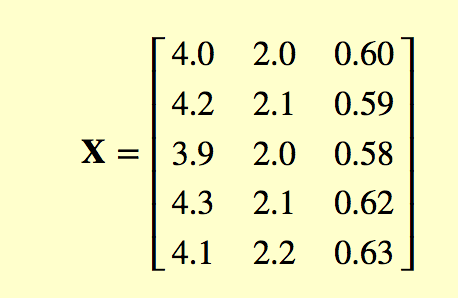

This is a matrix of a set with 5 observations, measuring 3 variables. This matrix can be described by its *mean vector* and *variance-covariance matrix*. The three variables, from left to right are length, width, and height of a certain object, for example. Each row vector **X **is another observation of the three variables (or components). The *mean vector* consists of the means of each variable (each column). The *variance-covariance matrix* consists of the variances of the variables along the main diagonal and the covariances between each pair of variables in the other matrix positions. The formula for computing the covariance of the variables *X* and *Y*  is 


$$cov = \frac{\sum_{i=1}^n (X_i - \bar{x})(Y_i - \bar{y})}{n-1}$$


in which $\bar{x} \text{ and } \bar{y}$ are the means of X and Y. The mean vector $\bar{x}$ and the co-variance matrix **S** for this sample data will be


$$\bar{x} = [4.10 \quad 2.08 \quad 0.604]


$$


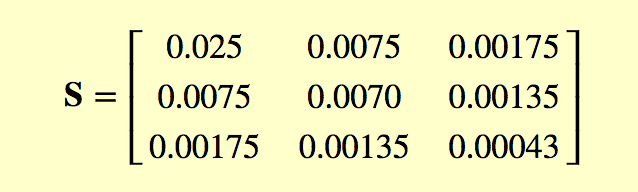

## Eigenvalue and Eigenvector

Imaging a model with the powers $A, A^2, A^3, ...$ of a square matrix. Now, you would like to get the $A^{100}$ power of that matrix. If you start with *A *and continue multiplying the matrices (so multiplying 100 matrices), it will get a bit cumbersome. You can get the $A^{100}
$using the [Eigenvalue](https://en.wikipedia.org/wiki/Eigenvalues_and_eigenvectors)s of matrix *A *(here they are 1 and 1/2). 

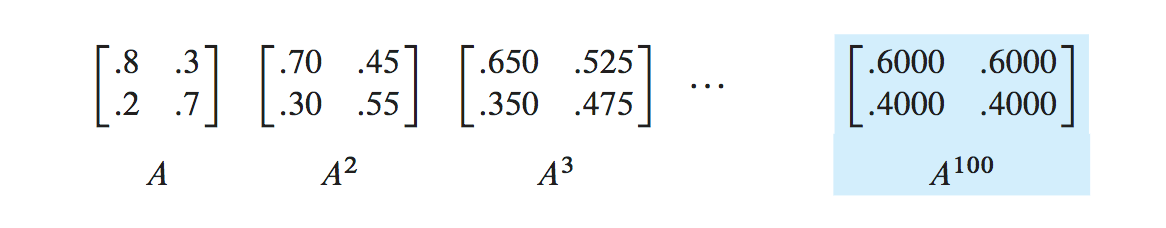

Certain vectors **x **are in the same direction as *A****x****, *and these we call [Eigenvector](https://en.wikipedia.org/wiki/Eigenvalues_and_eigenvectors). The basic equation is


$$Ax = \lambda x$$


the number *λ* is an eigenvalue of *A *and **x **is the eigenvector. The eigenvalue *λ *is a scalar of *A* and thus tells whether the vector **x **is stretched, shrunk, or reversed when it is mulitplied with *A*. To find the eigenvalues of the matrix A we use the [determinant](https://en.wikipedia.org/wiki/Determinant) $det(A - \lambda I) = 0$

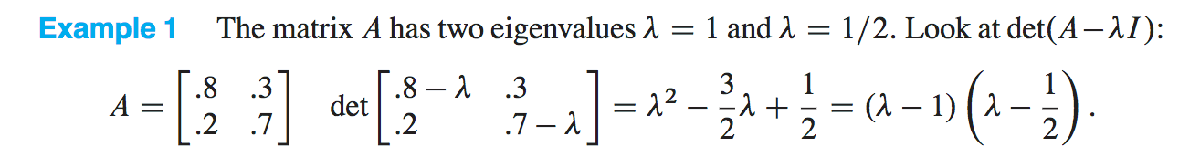

For these *λ*'s the matrix $A- \lambda I$ becomes a *singular *(zero determinant). Therefore, the eigenvectors $x_1 \text{ and } x_2$ are in the nullspace of $A - I \text{ and } A- \frac{1}{2} I$. To get the eigenvectors we use this nullspace equations:


$$(A - I) x_1 = 0 \text{ is } Ax_1 = x_1 \text{  and the first eigenvector is } (0.6, 0.4) \\
(A - \frac{1}{2}I) x_2 = 0 \text{ is } Ax_2 = \frac{1}{2}x_2 \text{  and the second eigenvector is } (1, -1) \\$$


For further derivations, look at [this page](http://math.mit.edu/~gs/linearalgebra/ila0601.pdf). And to get a nice visual representation of eigenvalues and eigenvectors, go [here](http://setosa.io/ev/eigenvectors-and-eigenvalues/). 

*In this exercise we use the digits data to extract principal components.   *

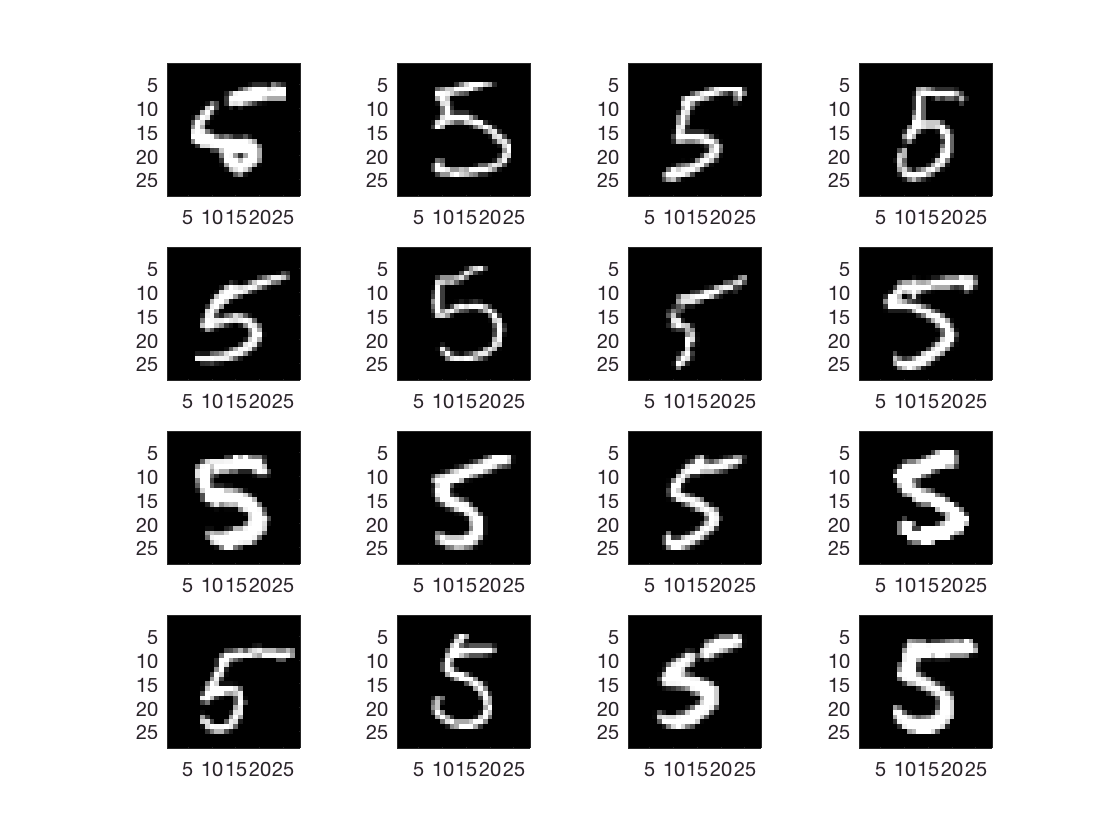

%% load the digits

data = load('digits.mat');

%% plot some individual numbers

figure;
for ii=[1:16]
    subplot(4,4,ii);
    imagesc(reshape(data.dig5(ii,:),[28 28])');
    set(gca,'dataa',[1 1 1]);
    colormap('gray');
end

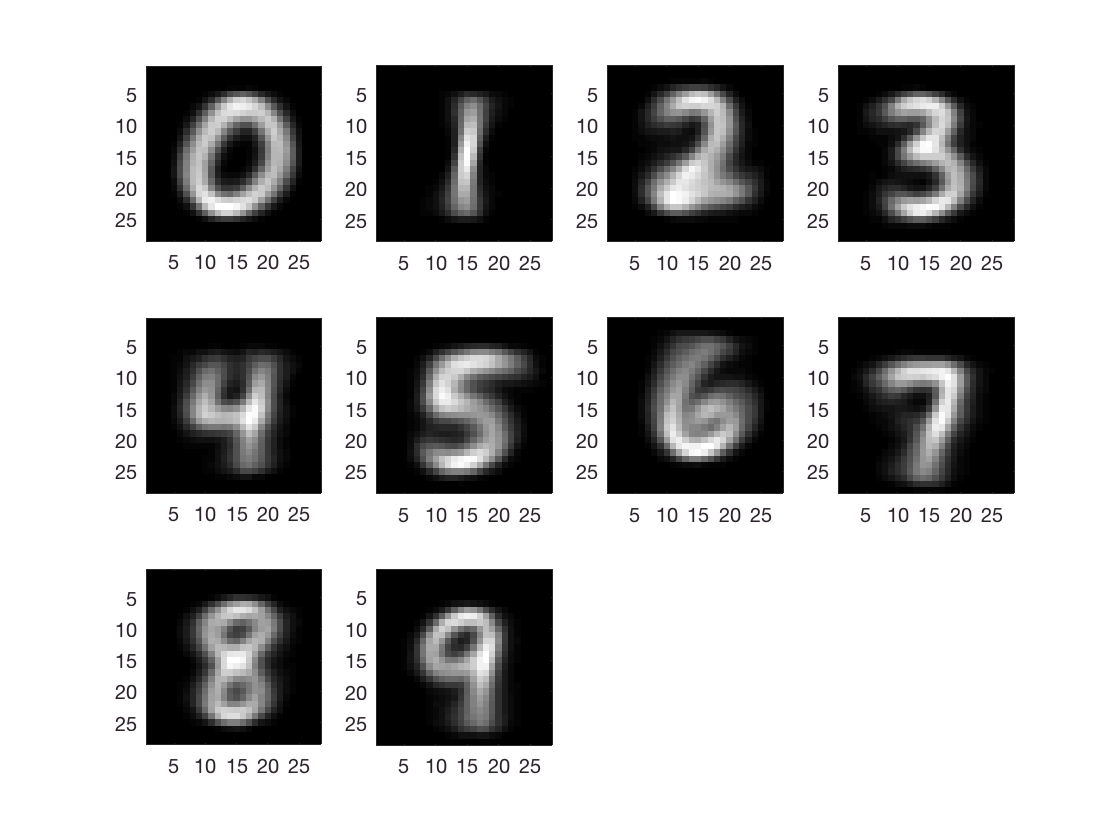


%% check it out

figure;
for ii=[0:9]
    subplot(3,4,ii+1); 
    eval(['imagesc(reshape(mean(data.dig' num2str(ii) ',1),[28 28])'');']);
    set(gca,'dataa',[1 1 1]);
    colormap('gray');
end

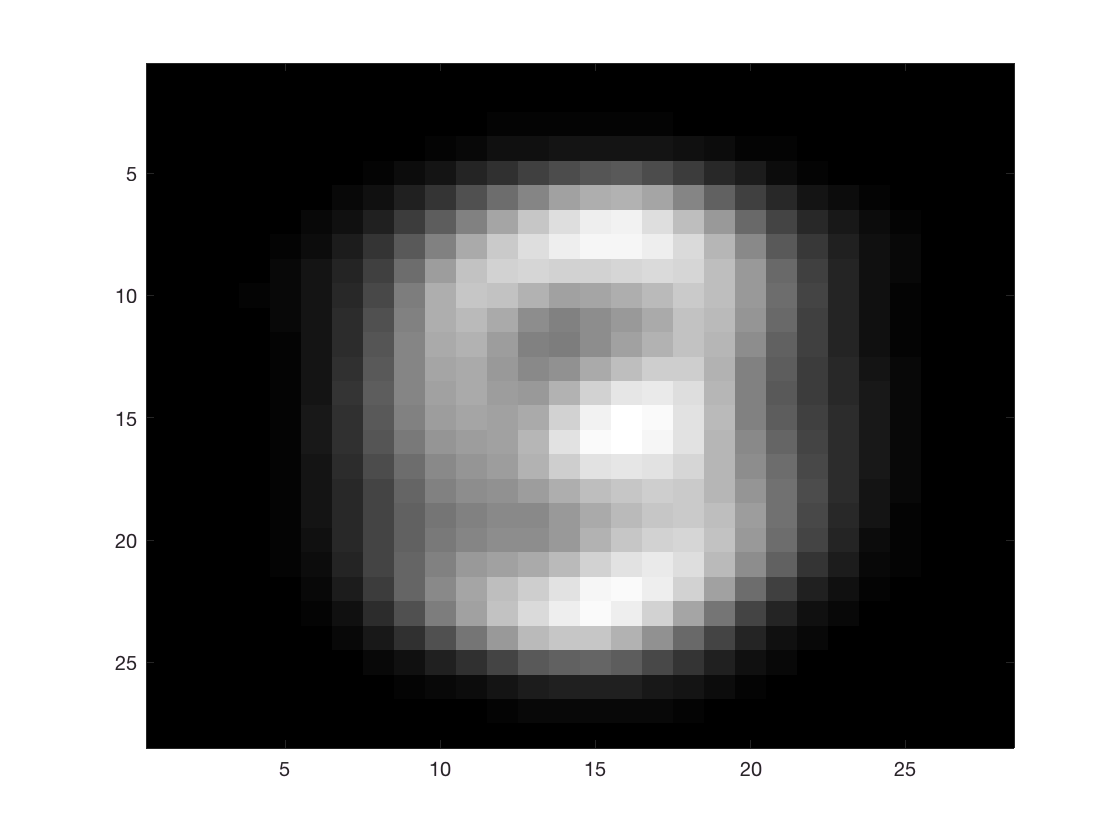

%% make giant matrix X with all numbers

X=[];
num=[];
for ii=[0:9]
    eval(['X = [X;data.dig' num2str(ii) '];']);
    num=[num;ones(400,1)*ii];
end


%% plot mean of the new ones

figure; imagesc(reshape(mean(X,1),[28 28])'); colormap('gray');

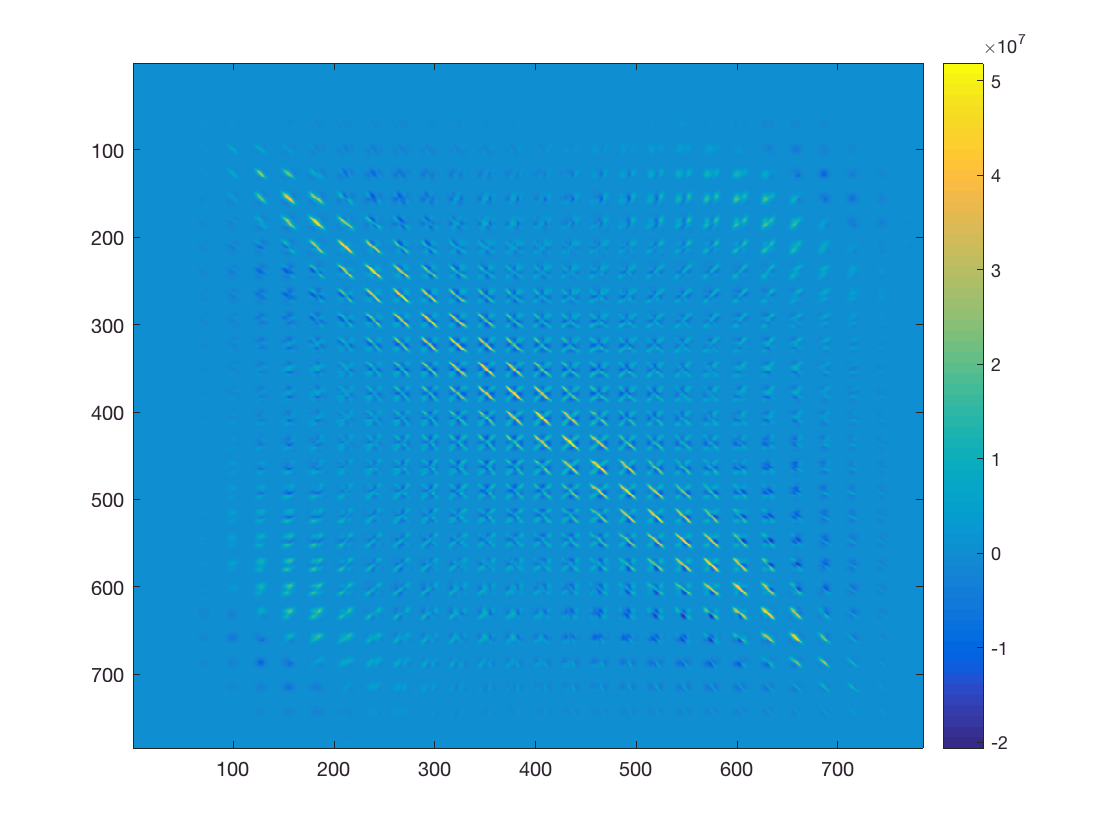

%% mean subtract X, compute the covariance matrix

X = double(X);
Xsave = X; % save it for later...
Xm = X - ones(size(X,1),1)*mean(X,1);
C = Xm'*Xm; %co-variance matrix
figure; imagesc(C); colorbar;

In scientific articles, you won't find this kind of PCA plot, you rather find that the eigenvalues such as these are easier to interpret than to visualize. 

Because the eigenvalues used in PCA are real and orthogonal, PCA expects your values to be orthogonal, and therefore fails to capture other interesting variances in your data.

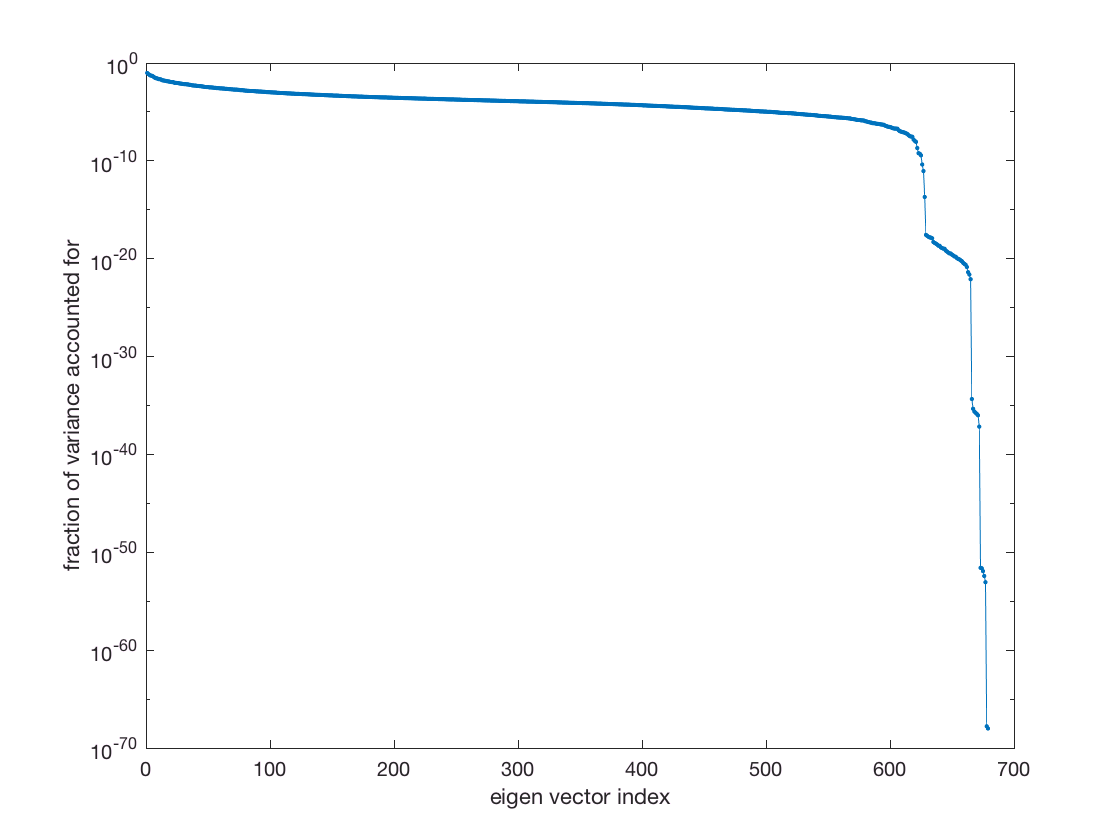

%% find all the eigenvectors and eigenvalues of this covariance matrix. 

[v,d]=eig(C);

d =diag(d); d = d/sum(d); % diag transforms the vector into a diagonal matrix, and vice versa

% it's all in reverse order
d=d(end:-1:1);
v = v(:,end:-1:1);

figure; plot(d,'.-'); xlabel('eigen vector index'); ylabel('fraction of variance accounted for');
set(gca,'yscale','log');

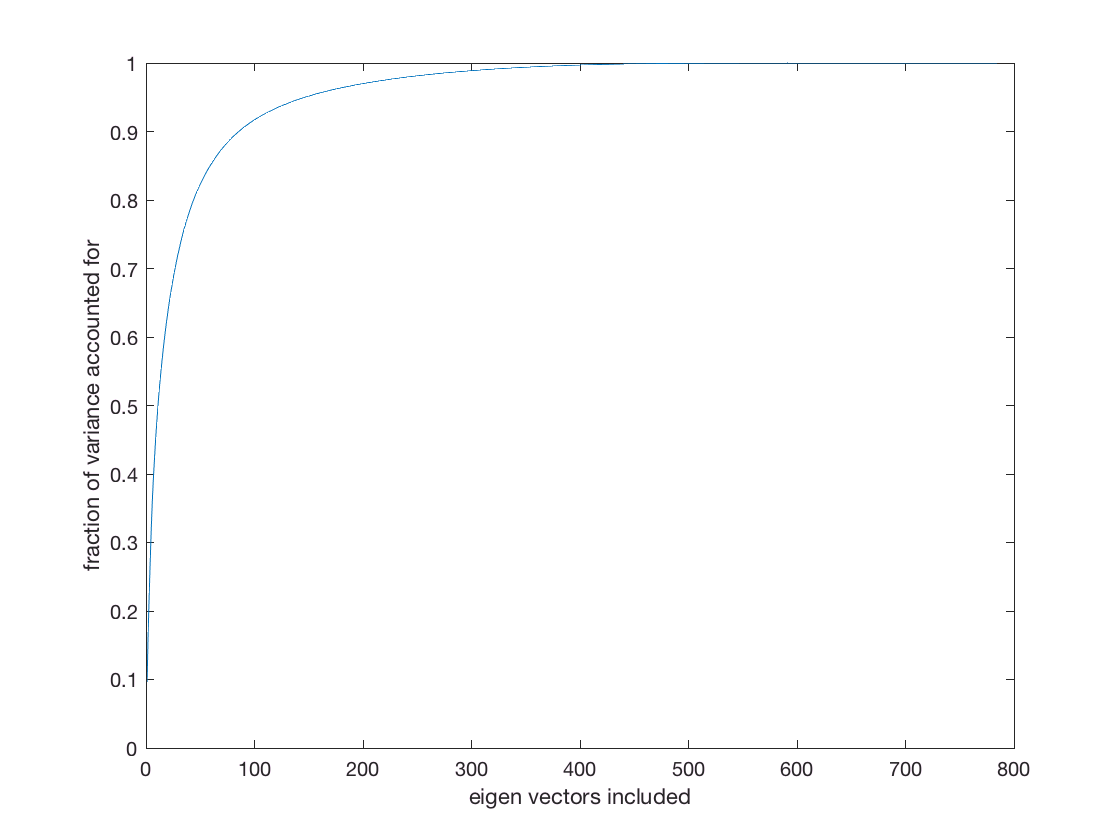

figure; plot(cumsum(d)); xlabel('eigen vectors included'); ylabel('fraction of variance accounted for');

This plotted the fraction of variance accounted for by every eigenvector. So your first eigenvectors already accounts for 90% of the variance of your data. The question then becomes: do you believe that the answer of your hypothesis is represented in these first amount of variance in your data. 

d(1:9) %the Eigenvalues 1 to 9 with their accounted amount of variance

ans =     0.0960
    0.0735
    0.0574
    0.0516
    0.0486
    0.0401
    0.0321
    0.0278
    0.0270


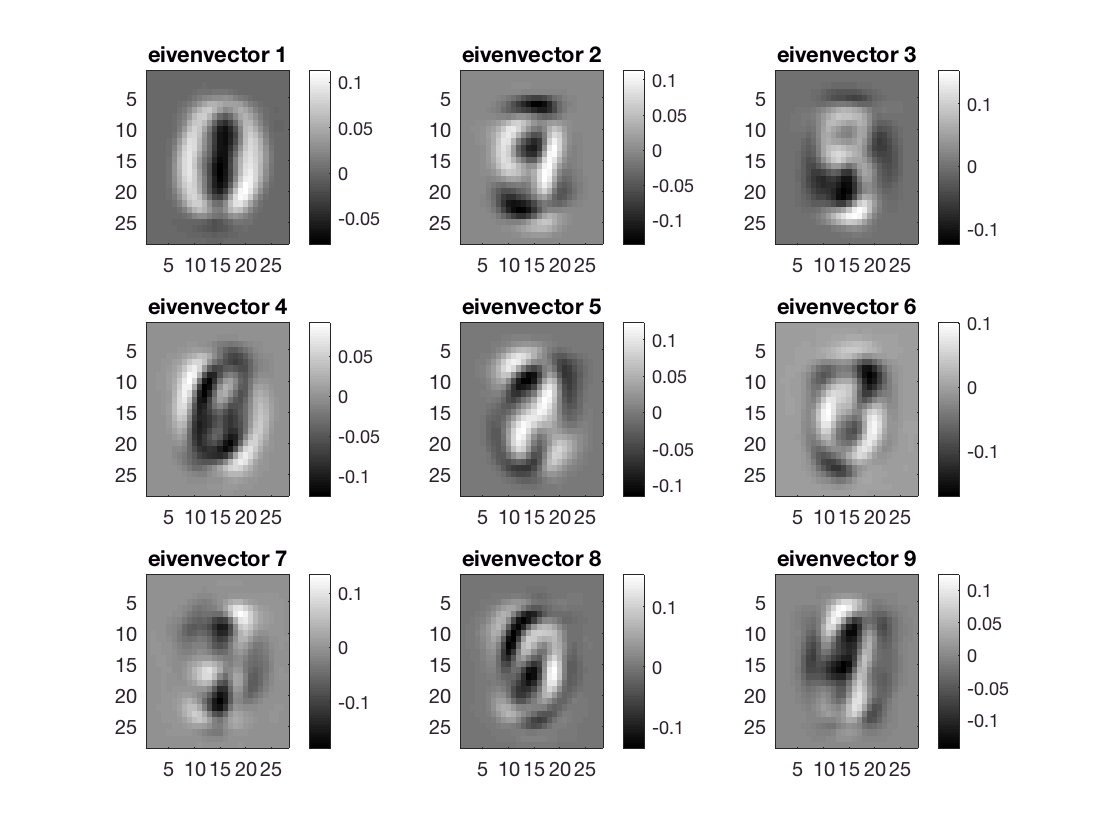

%% Plot the first few eigenvectors, just to check them out.
% These are a sort of mean digits now. (...) It depends on how orthogonal they are. 

figure
for ii=1:9
    subplot(3,3,ii);
    imagesc(reshape(v(:,ii),[28 28])'); colormap('gray'); colorbar;
    title(['eivenvector ' num2str(ii)]);
end

We are going to plot the point in the first two orthogonal eigenvectors. 

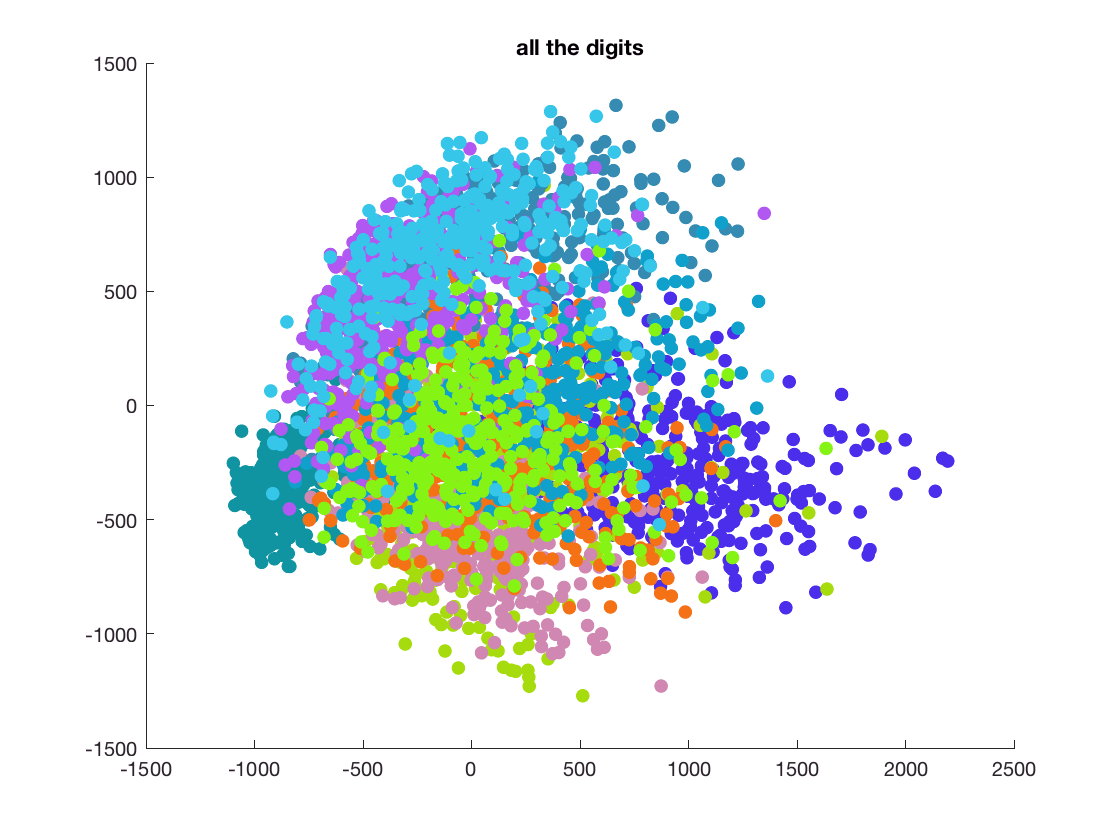

%% project all the points into the first two eigenvectors!

proj = Xm*v(:,1:2);

figure; hold on;
cm = colormap('lines');
for ii=0:9
    ind = [ii*400+1:(ii+1)*400];
%     plot(proj(ind,1),proj(ind,2),'.','color',cm(ii+1,:));
    plot(proj(ind,1),proj(ind,2),'.','color',rand(1,3),'markersize', 20);
end
title('all the digits');

Although it does well, it is not great. You could maybe destinguish one area, but you can't do anything with the overlapping points. 

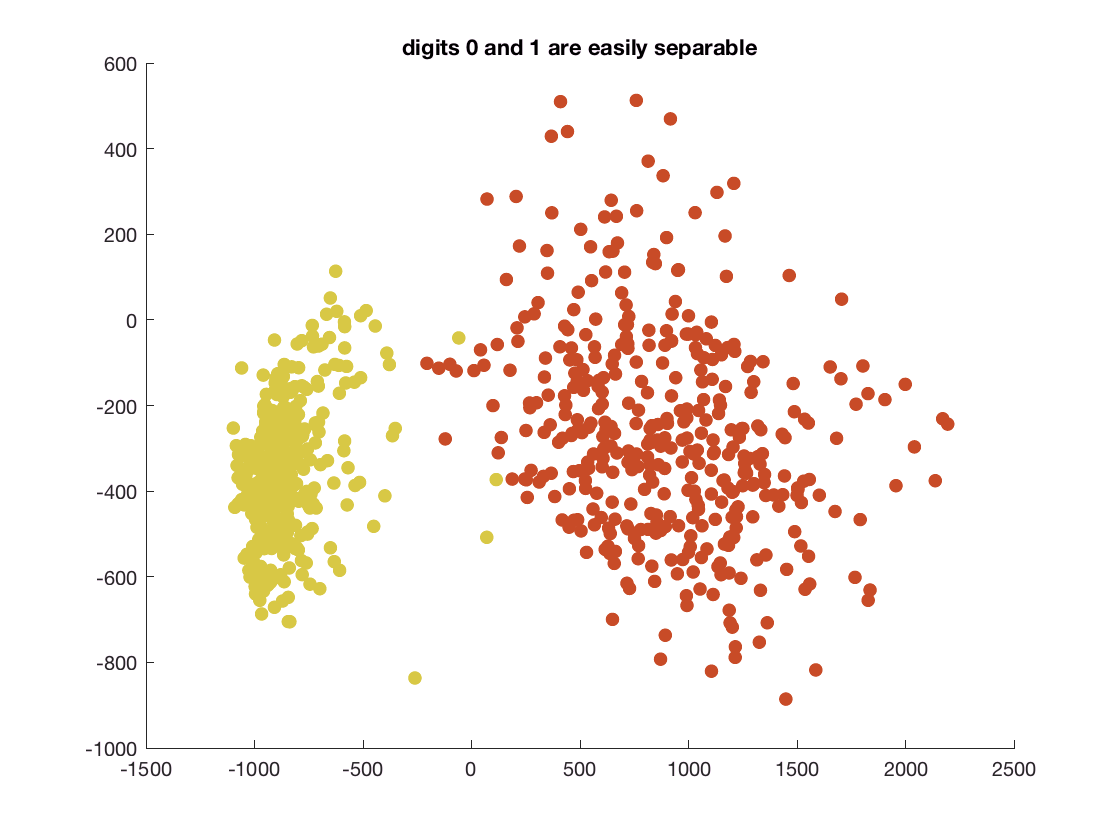

%% try just plotting digits 0 and 1

figure; hold on;
cm = colormap('lines');
for ii=0:1
    ind = [ii*400+1:(ii+1)*400];
%     plot(proj(ind,1),proj(ind,2),'.','color',cm(ii+1,:));
    plot(proj(ind,1),proj(ind,2),'.','color',rand(1,3),'markersize', 20);
end
title('digits 0 and 1 are easily separable');

Here we did a great job of separating the data points 1 and 0. Only one dimension matters here. 

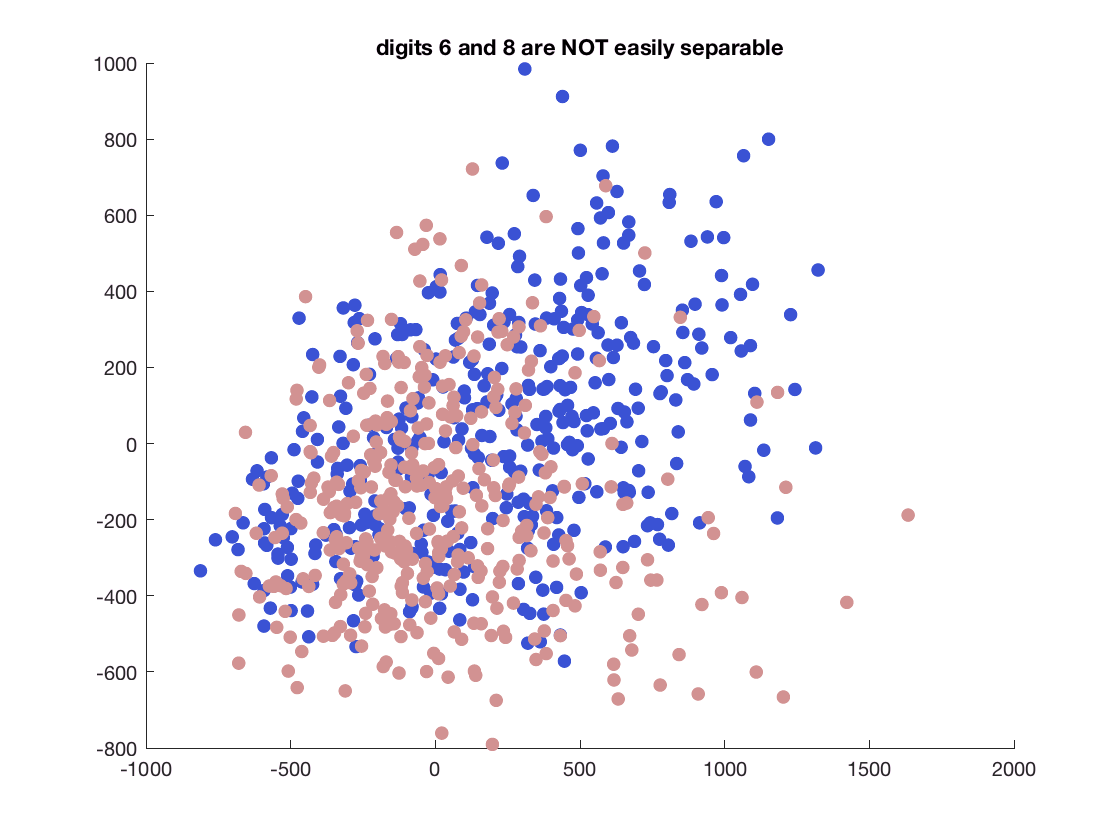

%% try just plotting digits 6 and 8

figure; hold on;
cm = colormap('lines');
for ii=[6,8]
    ind = [ii*400+1:(ii+1)*400];
%     plot(proj(ind,1),proj(ind,2),'.','color',cm(ii+1,:));
    plot(proj(ind,1),proj(ind,2),'.','color',rand(1,3),'markersize', 20);
end
title('digits 6 and 8 are NOT easily separable');

Plotting numbers 6 and 8 does not work out so great. What is weird here is that the data is forced to be orthogonal. So, you can't pick two directions that are not ortogonal. 

Because we based the PCA on all the included data, we get less separability of individual numbers. What happens when you only include the numbers 6 and 8 as your dataset? The numbers 6 and 8 will be more separable. 

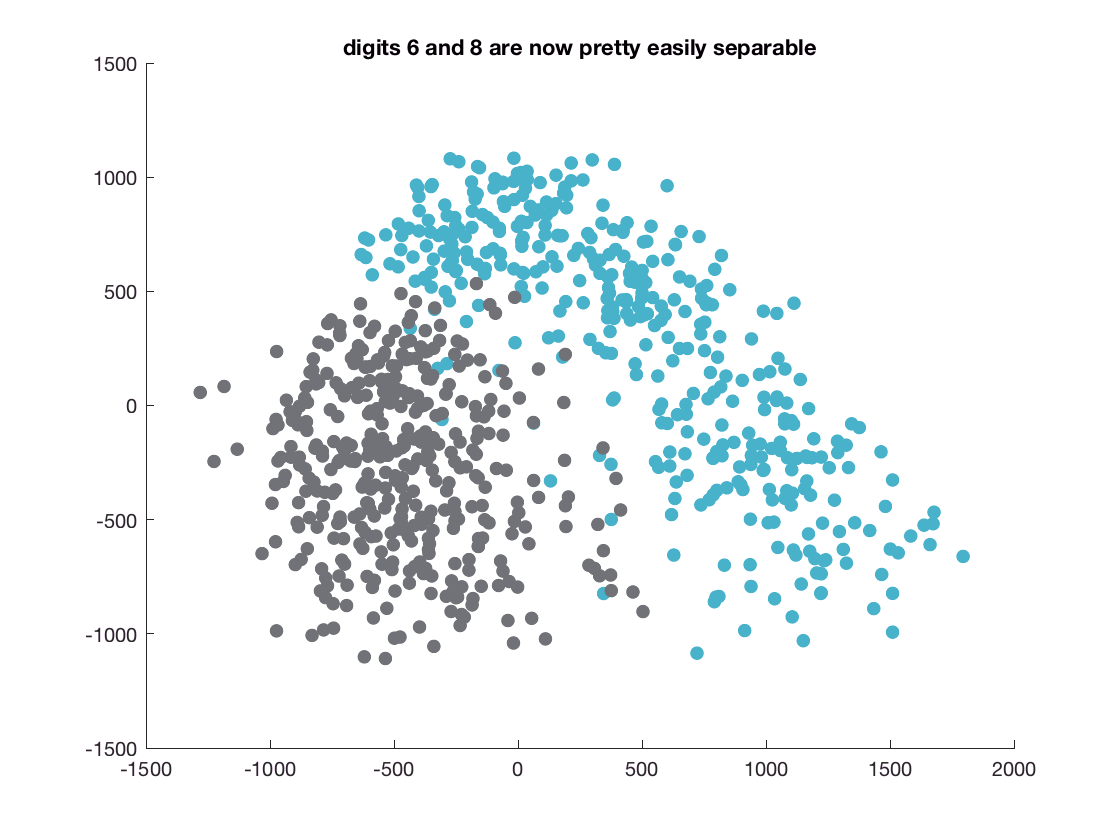

%% do PCA with just these digits

f=find((num==6) + (num==8));
X68=X(f,:);

X68m = X68 - ones(size(X68,1),1)*mean(X68,1);
C68 = X68m'*X68m;

[v68,d68]=eig(C68);
d68 =diag(d68); d68 = d68/sum(d68); 
d68=d68(end:-1:1);
v68 = v68(:,end:-1:1);

proj68 = X68m*v68(:,1:2);

figure; hold on;
cm = colormap('lines');
for ii=[0 1] % these are really 6 and 8
    ind = [ii*400+1:(ii+1)*400];
%     plot(proj(ind,1),proj(ind,2),'.','color',cm(ii+1,:));
    plot(proj68(ind,1),proj68(ind,2),'.','color',rand(1,3),'markersize', 20);
end
title('digits 6 and 8 are now pretty easily separable');

The PCA you find is highly dependable on the amount of data you give as an input. The more data you add, the less separable your points are going to be. 

## Linear Discriminant Analysis 

[Linear discriminant analysis](https://en.wikipedia.org/wiki/Linear_discriminant_analysis) (LDA) is most commonly used as dimensionality reduction technique in the pre-processing step for pattern-classification. It is a generalization of* Fisher's linear discriminant* to find a linear combination of [features](https://en.wikipedia.org/wiki/Features_%28pattern_recognition%29) that characterizes or separates two or more classes of objects or events. The resulting combination may be used as a linear classifier, or, more commonly, for [dimensionality reduction](https://en.wikipedia.org/wiki/Dimensionality_reduction) before later classification. LDA works when the measurements made on independent variables for each observation are continuous quantities. 

LDA is closely related to *analysis of variance (ANOVA) *and* regression analysis*, which also attempt to express one dependent variable as a linear combination of other features. However, ANOVA uses categorical independent variables and a continuous dependent variable, whereas LDA has continuous independent variables and a categorical dependent variable (i.e. the class label). LDA is also closely related to *PCA* and *factor analysis* in that they both look for linear combinations of variables which best explain the data. Both LDA and PCA are linear transformation techniques that are commonly used for dimensionality reduction. PCA can be described as an “unsupervised”  algorithm, since it “ignores” class labels and its goal is to find the directions (the principal components) that maximize the variance in a dataset. In contrast to PCA, LDA is “supervised” and computes the directions  (“linear discriminants”) that will represent the axes that that  maximize the separation between multiple classes. 

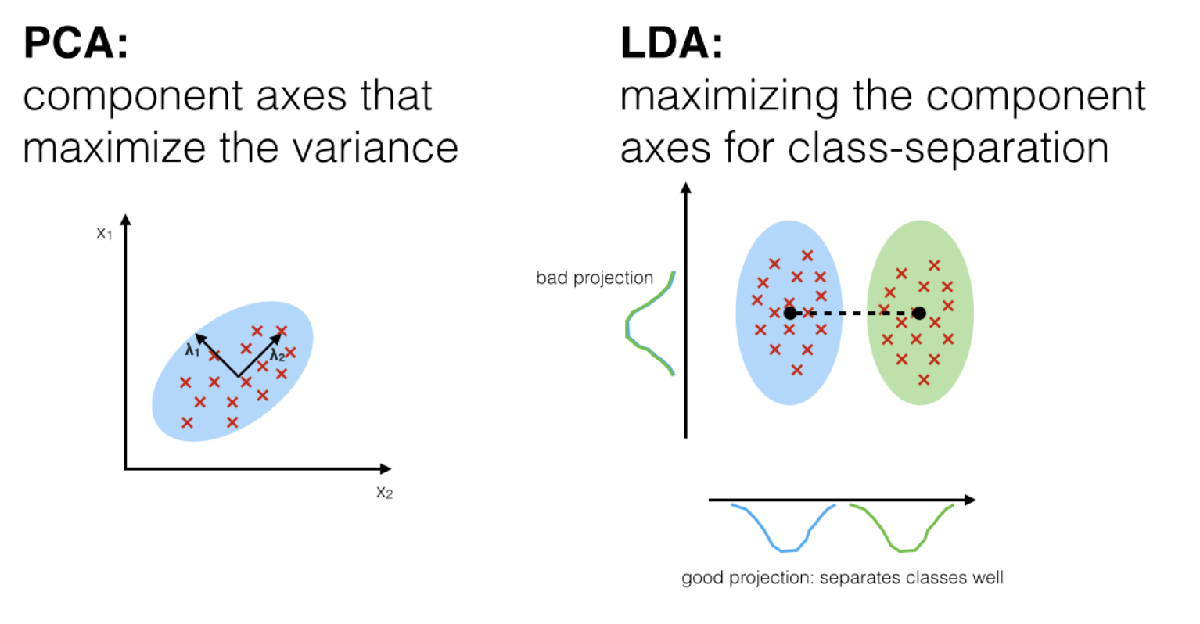

Your ideal vector could be based on a non-linear angle. LDA finds this vector that captures the separation of the data, by using the inverse of the co-variance matrix. Using the inverse of the co-variance matrix you can estimate how the co-variance looks like and to correct for this variance, a vector is created that indicates the separation of your data. Your PCA won't find it, because it is only looking for orthogonal vectors.

*Now, let's run LDA on 6 and 8, and we can see how much better it looks. It turns out C68 has zero eigenvalues, so it's not easily invertible. To deal with this, we'll add elements along its diagonal...*

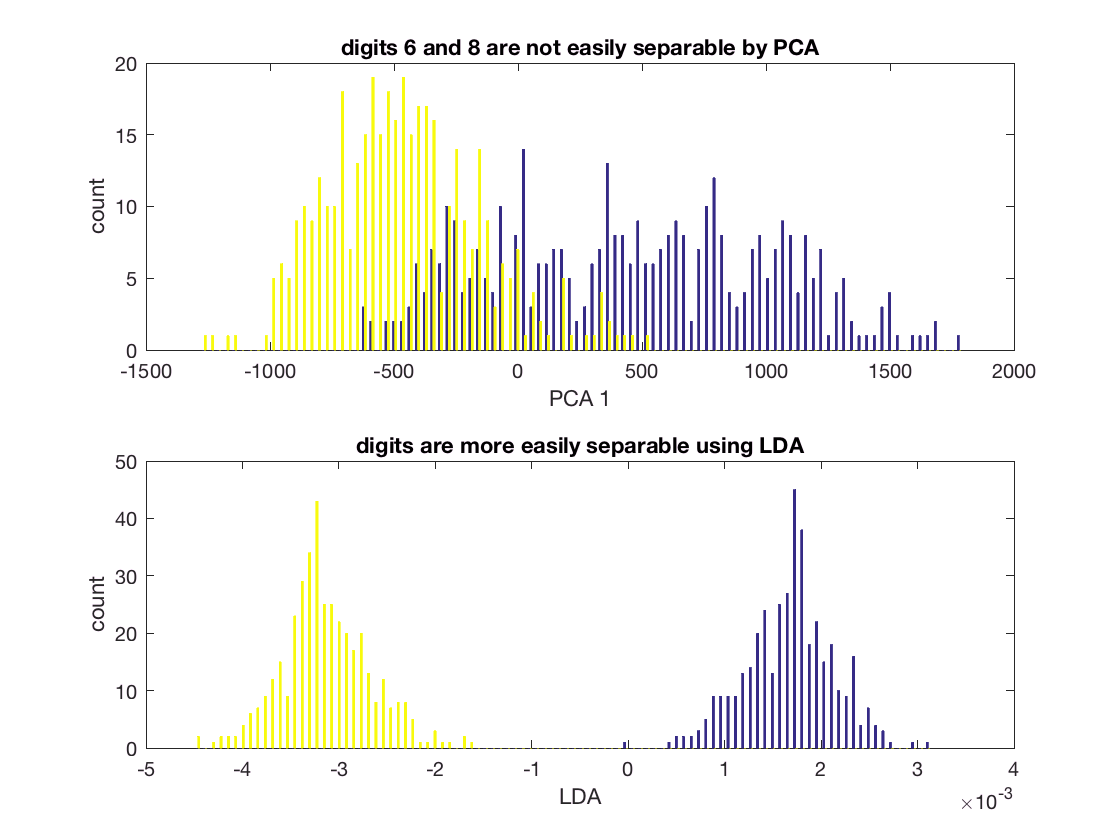

%C68^-1; %gives an error as this didn't change the Identity matrix
%C86r = C68 + eye(size(C68))+mean(d68);
%C68r^-1 % this is a change of the identity matrix C68. Although we didn't change much

C68r = C68 + eye(size(C68))*mean(d68);

w = (mean(X68(1:400,:),1)-mean(X68(401:800,:),1))/C68r; 
p = X68*w';

figure;
subplot(2,1,1);
hist([proj68(1:400,1),proj68(401:800,1)],100);
xlabel('PCA 1');
ylabel('count');
title('digits 6 and 8 are not easily separable by PCA');

subplot(2,1,2);
hist([p(1:400),p(401:800)],100);
xlabel('LDA');
ylabel('count');
title('digits are more easily separable using LDA');

You take the dot product of all your data points and plot them together.  

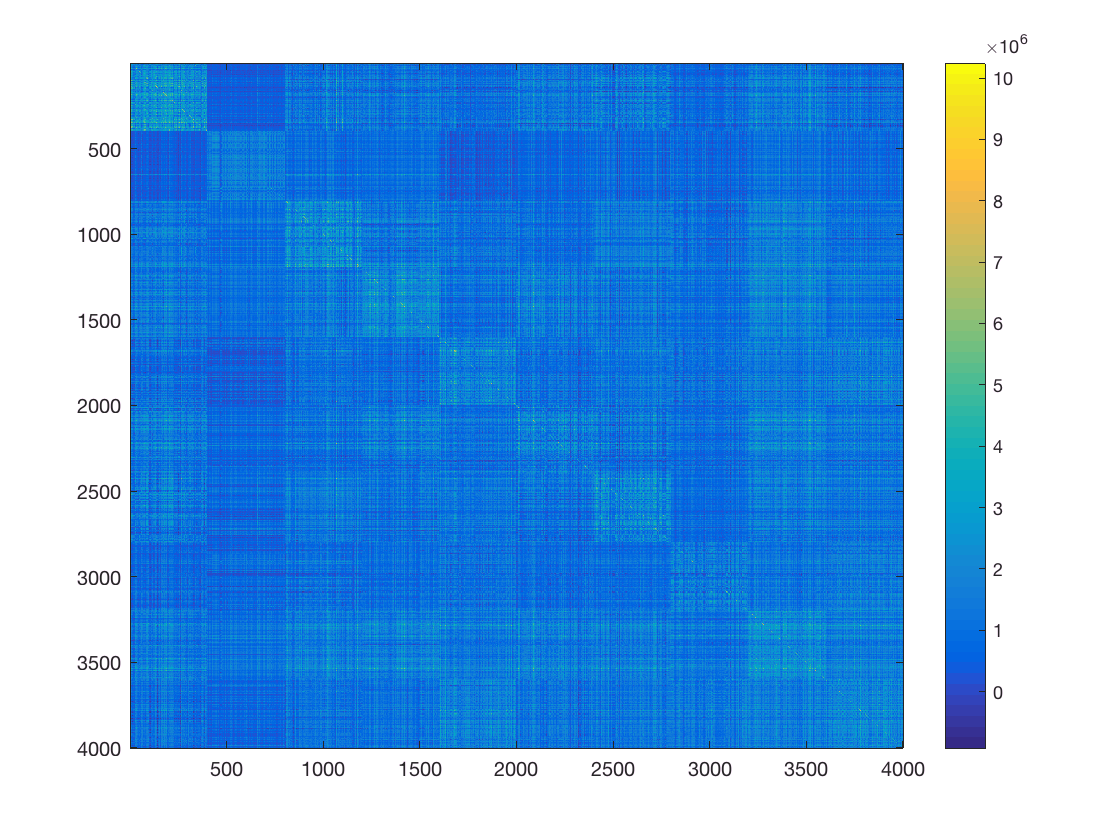

%% btw, of course we can also view each pixel as a data point, and each handwritten
%% digit as a feature; in other words, caring about X transpose; let's repeat
%% a bunch of what we did but with X' instead

X = Xsave';

Xm = X - ones(size(X,1),1)*mean(X,1);
C = Xm'*Xm;
figure; imagesc(C); colorbar;

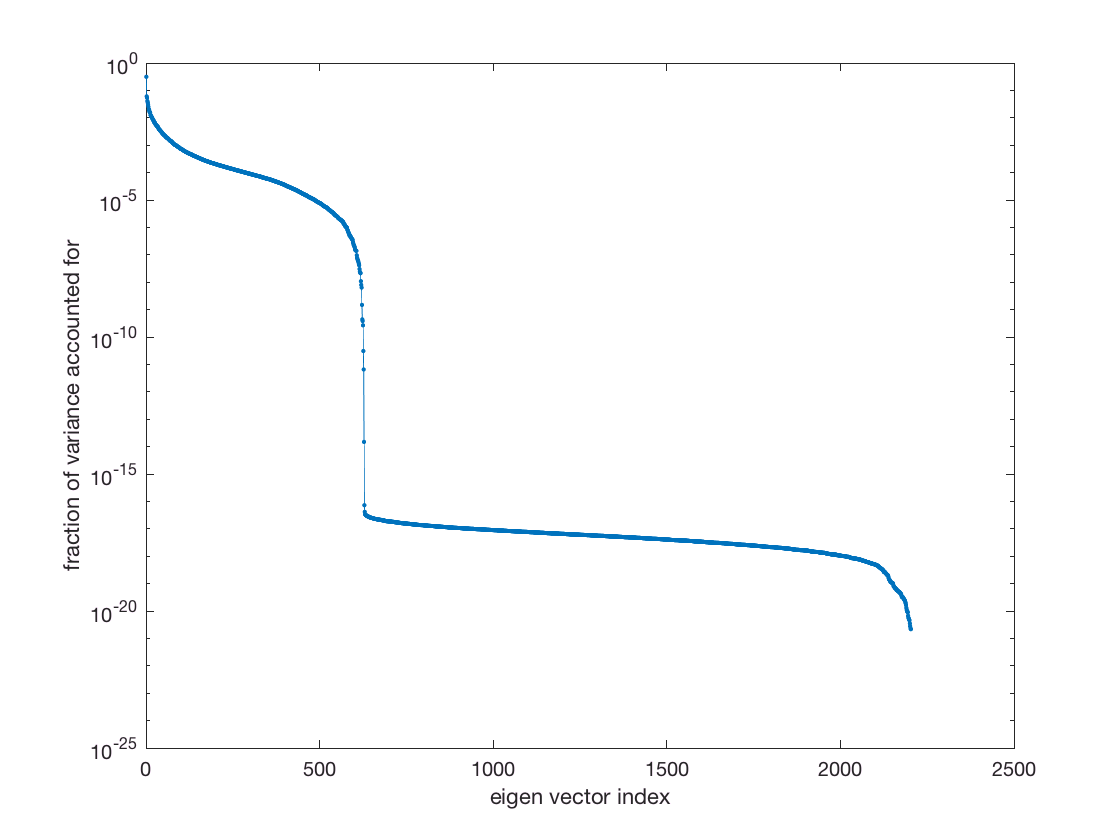

% note: dimensions are now the digit index, not pixel index;

%% this may take a little while, since it's a big covariance matrix
[v,d]=eig(C);

d =diag(d); d = d/sum(d); 

% it's all in reverse order
d=d(end:-1:1);
v = v(:,end:-1:1);

%% now, plot some of this stuff up

figure; plot(d,'.-'); xlabel('eigen vector index'); ylabel('fraction of variance accounted for');
set(gca,'yscale','log');

This is the fraction of variance accounted by each of the PCA components. The bump in the co-variance matrix is because you should get a max of 800 eigen vectors. 

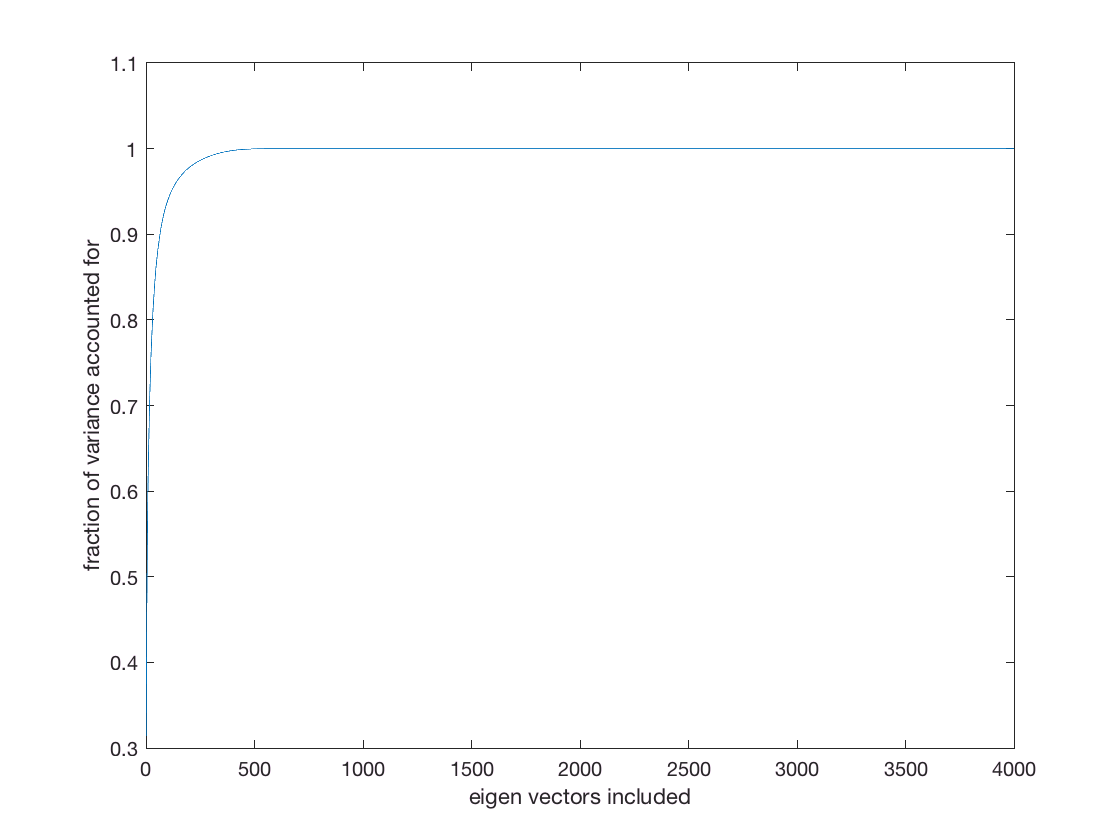

figure; plot(cumsum(d)); xlabel('eigen vectors included'); ylabel('fraction of variance accounted for');

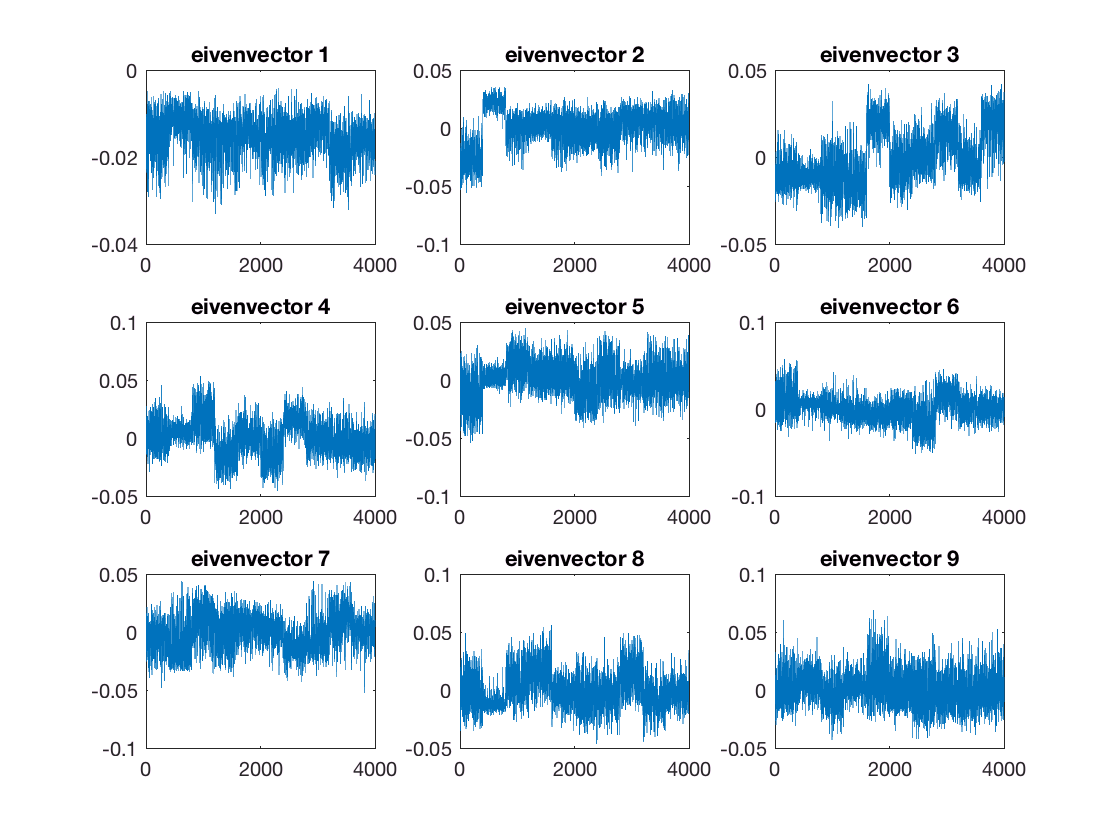


figure;
for ii=1:9
    subplot(3,3,ii);
    plot(v(:,ii));
    title(['eivenvector ' num2str(ii)]);
end

## Linear separation

You can view your data in several different directions. Depending on your data, you choose the right representation of the variance in your data. Both PCA and LDA are linear separation. [Linear separation](https://en.wikipedia.org/wiki/Linear_separability) is the Euclidean geometric property of a pair of sets of points that are separable if there exist at least one line in the plane with all the blue points on one side of the line and all the red points on the other side. The following example are three non-collinear points in two classes (+ and -) 

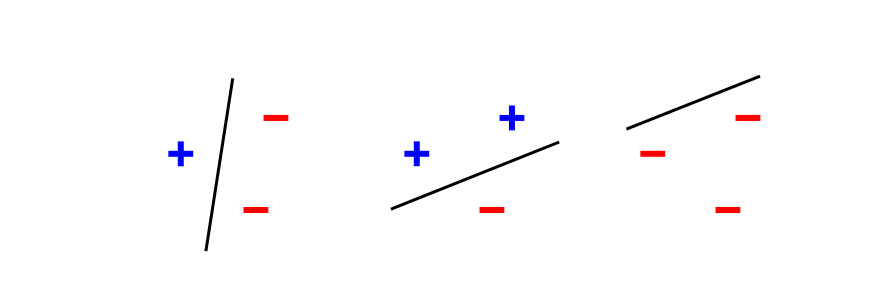

However, not all sets of four points, no three collinear, are linearly  separable in two dimensions. The following example would need *two* straight lines and thus is not linearly separable:

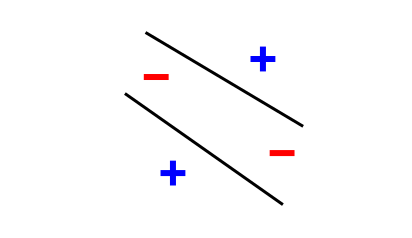

It is always a good start to perform PCA first to capture your higher dimensionality of your data. In this way, you can capture outliers of your data. Furthermore, other tools to capture other structures in your data make use of [skeweness and kurtosis](http://www.itl.nist.gov/div898/handbook/eda/section3/eda35b.htm), in addition to characterizing the location and variability in your data set. *Skewness *is a measure of symmetry, or more precisely, the lack of symmetry. A distribution, or data set, is symmetric if it looks the same to the left and right of the center point. *Kurtosis *is a measure of whether the data are heavy-tailed or light-tailed relative to a normal distribution. That is, data sets with high kurtosis tend to have heavy tails, or outliers. Data sets with low kurtosis tend to have light tails, or lack of outliers. When your data is non-Gaussian you can use [Independent Component Analysis (ICA)](https://en.wikipedia.org/wiki/Independent_component_analysis), where kurtosis is used to find the correct weight vectors to deal with the non-normality, or gaussiantiy, of the data. ICA is a technique to separate linearly mixed sources, i.e. separating a multivariate signal into additive subcomponents. This is done by assuming that the subcomponents are non-Gaussian signals and that they are statistically independent from each other. A common example application is the "[cocktail party problem](https://en.wikipedia.org/wiki/Cocktail_party_problem)" of listening in on one person's speech in a noisy room. 

What methods works best for your data set depends on the characteristics of your data, of which [correlation and independence](https://en.wikipedia.org/wiki/Correlation_and_dependence) are very important. *Dependence* is any statistical relationship, whether causal or not, between two random variables.* Correlation* is any of a broad class of statistical relationships involving dependence, though in common usage it most often refers to the extent to which two variables have a linear relationship with each other. An example of dependent phenomena include the correlation between the physical statures of parents and their offspring, and the correlation between the demand for a product and its price. If two variables are un-correlated (their expected value is 0) you use PCA, if these variables are correlated but your data is independent, you can use ICA.

## Non-linear separation

PCA will not necessarily allow you to separate datasets, for example this type of data set:

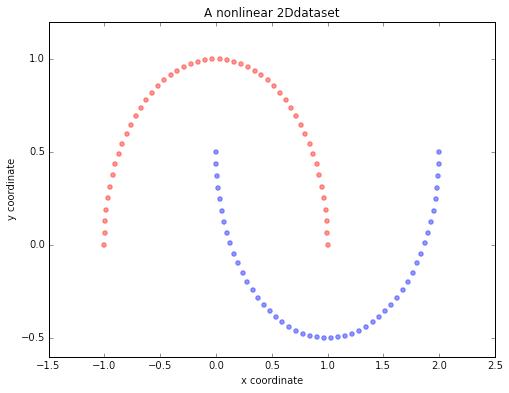

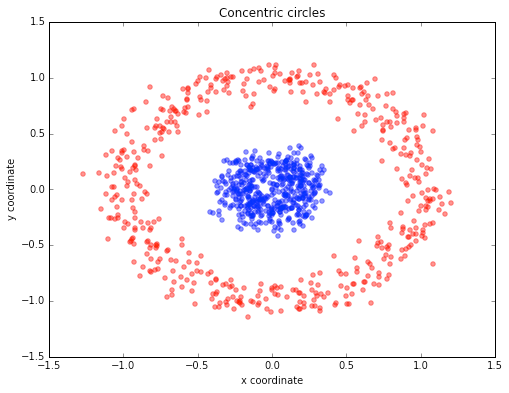

If you can separate your data linearly, you are in a good place. However, sometimes this doesn't work out and the next step is then to use a nonlinear method, which typically involves applying some type of transformation to your input dataset. After the transformation, many techniques then try to use a linear method for separation. Non-linear datasets are sets of data points that are crossing each other, covering each other, or variance difference, and you can separate this using non-linear transformation.  

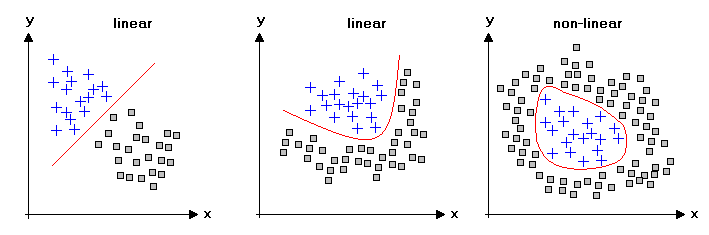

[t-distributed stochastic neighbor embedding](https://en.wikipedia.org/wiki/T-distributed_stochastic_neighbor_embedding) (t-SNE) is a non-linear dimensionality reduction technique that is particularly well-suited for embedding high-dimensional data into a space of two or three dimensions, which can then be visualized in a scatter plot. Specifically, it models each high-dimensional object by a two- or  three-dimensional point in such a way that similar objects are modeled by nearby points and dissimilar objects are modeled by distant points. It is developed by [van der Maaten & Hinton](https://lvdmaaten.github.io/tsne/) to visualize patterns using MNIST database of hand-written digits.